L1=25e-3; %side length
M=5000; %number of samples
dx1=L1/M; %src sample interval
x1=-L1/2:dx1:L1/2-dx1; %src coords
y1=x1;
lambda=0.5*10^-6; %wavelength
k=2*pi/lambda; %wavenumber
w=0.051; %source half width (m)

%parameters for HG00 input signals
w_in = 0.5e-3;        %width of HG00 signal
d = 10e-4;           %distance between centers of neighbour gaussian beams
f = 0.25;           %focus length of lens
r = 0.0125          %radius of lens

r = 0.0125

P=circle_window(x1,y1,r); %window for lens.

%generate two HG00 input signals

[X1,Y1]=meshgrid(x1,y1);

uin =  zeros(length(X1),length(Y1));
for i = -1:1
    for j = -1:1
        xc = d*i;
        yc = d*j;
        uin = uin +  exp(-((X1-xc).^2 + (Y1-yc).^2)/(w_in^2));
    end
end

I1=abs(uin.^2); %src irradiance


%Plot input signal 

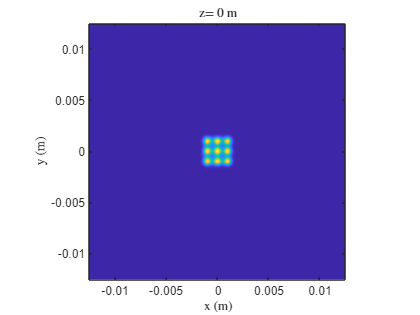

figure(1)
imagesc(x1,y1,I1);
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title('z= 0 m')

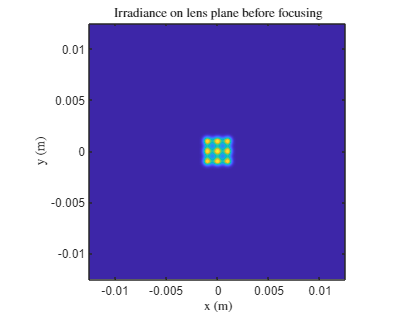

u2=propTF(uin,L1,lambda,f); %propagation
% uout=propIR(uin,L1,lambda,f); %propagation
u2 = u2.*P;
I2=abs(u2.^2); %src irradiance

x2=x1; %obs coords
y2=y1;

figure(2) %display obs irrad
imagesc(x2,y2,I2);%stretch image contrast
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title('Irradiance on lens plane before focusing');

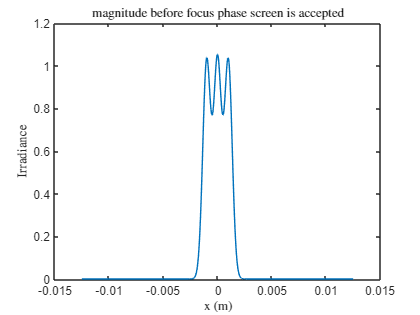


 %irradiance profile according to x axis
figure(3) 
plot(x2,abs(u2(M/2+1,:)));
xlabel('x (m)'); ylabel('Irradiance');
title('magnitude before focus phase screen is accepted');

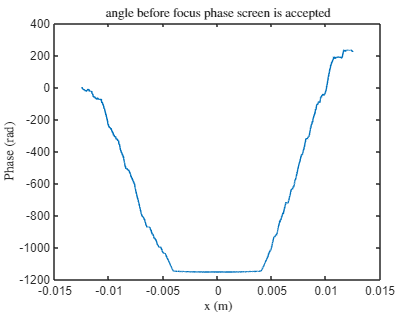


%plot obs field phase
figure(4) 
plot(x2,unwrap(angle(u2(M/2+1,:))));
xlabel('x (m)'); ylabel('Phase (rad)');
title('angle before focus phase screen is accepted');

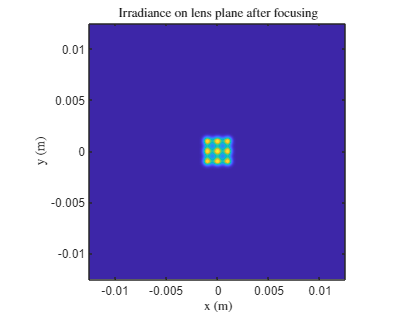


u2f=focus(u2,L1,lambda,f); %phase screen for first lens
I2f=abs(u2f.^2); %src irradiance

figure(5) %display obs irrad
imagesc(x2,y2,I2f);%stretch image contrast
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title('Irradiance on lens plane after focusing');

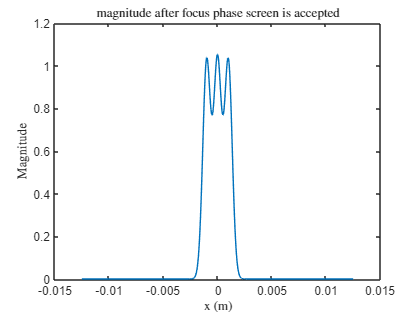


 %irradiance profile according to x axis
figure(6) 
plot(x2,abs(u2f(M/2+1,:)));
xlabel('x (m)'); ylabel('Magnitude');
title('magnitude after focus phase screen is accepted');

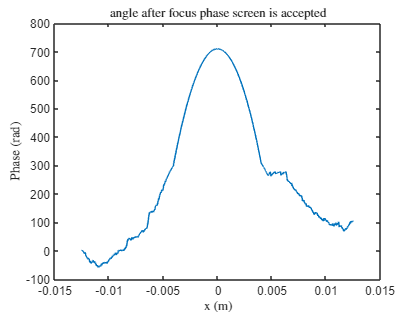


%plot obs field phase
figure(7) 
plot(x2,unwrap(angle(u2f(M/2+1,:))));
xlabel('x (m)'); ylabel('Phase (rad)');
title('angle after focus phase screen is accepted');


u3=propTF(u2f,L1,lambda,f); %propagation to get the signal on back focus plane of first lens

% uout=propIR(uout,L1,lambda,f); %propagation
I3=abs(u3.^2); %obs irrad


%Plot output signal

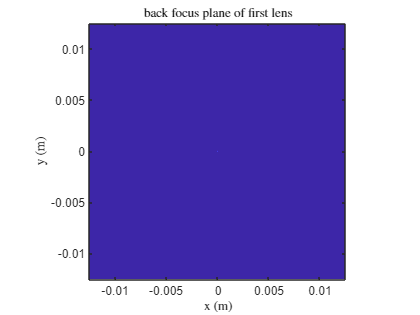

figure(8) %display obs irrad
imagesc(x2,y2,I3);%stretch image contrast
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title('back focus plane of first lens');

u4=propTF(u3,L1,lambda,f); %get signal on lens plane of second lens
I4=abs(u4.^2); %obs irrad

figure(9) %display obs irrad
imagesc(x2,y2,I4);%stretch image contrast
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title('Irradiance on second lens plane');



u4f=focus(u4,L1,lambda,f);
u5=propTF(u4f,L1,lambda,f); %propagation
I5=abs(u5.^2); %obs irrad


figure(10) %display obs irrad
imagesc(x2,y2,I5);%stretch image contrast
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title(['Irradiance on back focus plane of second lens']);

u6=propTF(u5,L1,lambda,99*f); %propagation
I6=abs(u6.^2); %obs irrad

figure(11) %display obs irrad
imagesc(x2,y2,I6);%stretch image contrast
axis square; axis xy;
xlabel('x (m)'); ylabel('y (m)');
title(['Irradiance on 100*f plane after second lens']);
